## TS1

Pregunta 1

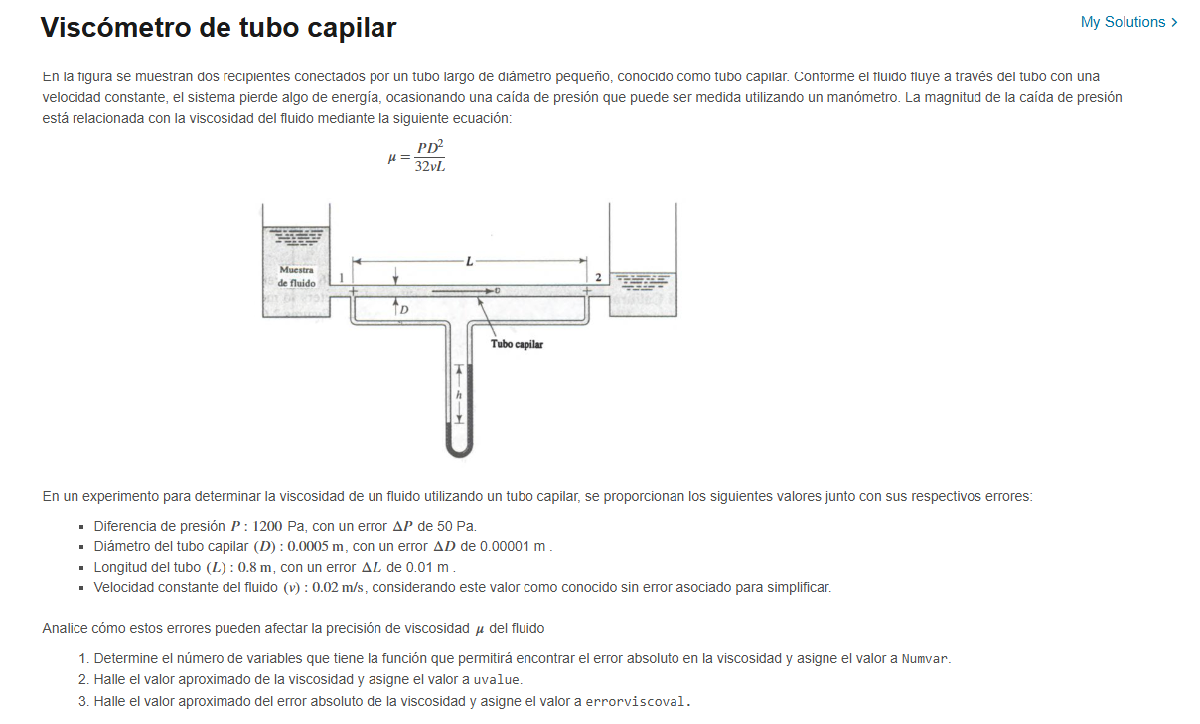

% Datos del problema
P = 1200; % Diferencia de presión en Pa
dP = 50; % Error en la diferencia de presión en Pa
D = 0.0005; % Diámetro del tubo en metros
dD = 0.00001; % Error en el diámetro en metros
L = 0.8; % Longitud del tubo en metros
dL = 0.01; % Error en la longitud en metros
v = 0.02; % Velocidad del fluido en m/s (valor conocido, sin error)

% 1. Determinar el número de variables que afectan a la viscosidad
Numvar = 3 % complete aqui

Numvar =      3



% 2. Hallar el valor aproximado de la viscosidad
% Ecuación para la viscosidad, basada en Hagen-Poiseuille:
uvalue= ( P*(D)^2 ) / ( 32*v*L)              %complete aqui

uvalue =      5.859375000000000e-04





% 3. Propagación del error usando derivadas parciales sin raíces cuadradas
% Derivadas parciales de la función mu respecto a P, D, y L:
dmu_dP = (D^2) / (32 * v * L);        % Derivada parcial respecto a P
dmu_dD = (2 * P * D) / (32 * v * L);  % Derivada parcial respecto a D
dmu_dL = -(P * D^2) / (32 * v * L^2); % Derivada parcial respecto a L

% Propagación de errores
errorP = abs(dmu_dP) * dP; % Error debido a P
errorD = abs(dmu_dD) * dD; % Error debido a D
errorL = abs(dmu_dL) * dL; % Error debido a L


% Calcular el error absoluto en la viscosidad 
errorviscoval = errorP + errorD + errorL        %complete aqui

errorviscoval =      5.517578125000000e-05


Nota: 100%

Pregunta 2

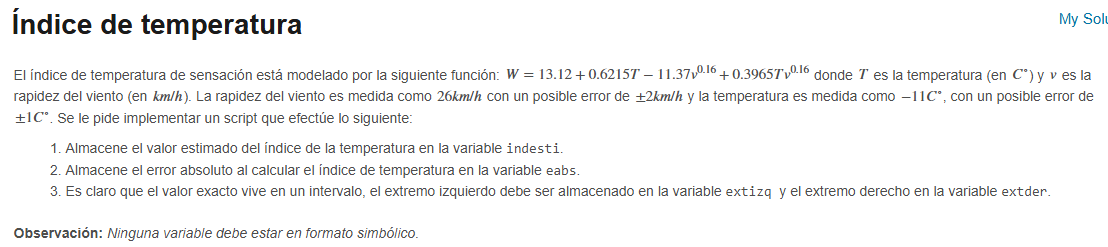

% use cálculo simbólico
syms t v
w= 13.12 + 0.6215*t - 11.37*v^(0.16) + 0.3965*t*v^(0.16)

$$w = \frac{1243\,t}{2000}+\frac{793\,t\,v^{4/25}}{2000}-\frac{1137\,v^{4/25}}{100}+\frac{328}{25}$$

%
t_val = -11;  % Valor de t
v_val = 26;   % Valor de v

% Sustituir los valores
indesti= double(subs(w, [t, v], [t_val, v_val]))

indesti =  -20.211618746849219



% 
w_t = diff(w,t)

$$w\_t = \frac{793\,v^{4/25}}{2000}+\frac{1243}{2000}$$

w_v = diff(w,v)

$$w\_v = \frac{793\,t}{12500\,v^{21/25}}-\frac{1137}{625\,v^{21/25}}$$


w_t_eval = double(subs(w_t,[t,v],[t_val,v_val]))

w_t_eval =    1.289288486992703


w_v_eval = double(subs(w_v,[t,v],[t_val,v_val]))

w_v_eval =   -0.163046884595995



eabs= abs(w_t_eval)*1 + abs(w_v_eval)*2

eabs =    1.615382256184694



% 
extizq=indesti-eabs

extizq =  -21.827001003033914


extder=indesti+eabs

extder =  -18.596236490664523


Pregunta 3

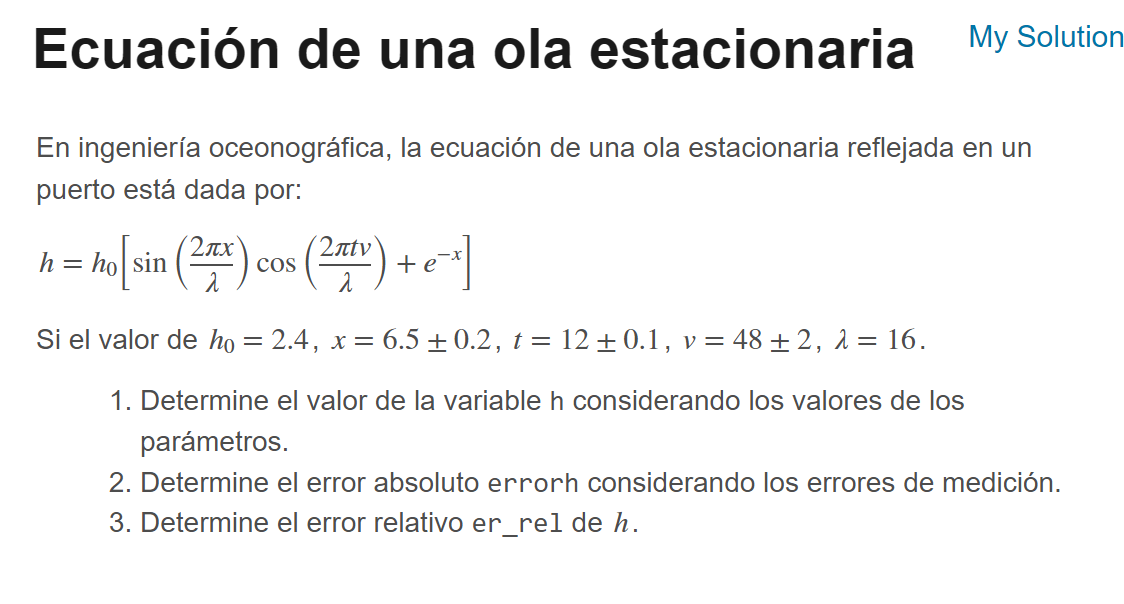

% No usar los comandos clear, ni clc.
%clear
h0=2.4; lbda=16;
x_err = 0.2;
t_err = 0.1;
v_err = 2;
syms x t v
% ítem 1
h_func = h0* (sin( (2*pi*x) / (lbda) )* cos( (2*pi*t*v) / (lbda) ) + exp(-x) )

$$h\_func = \frac{12\,{\mathrm{e}}^{-x}}{5}+\frac{12\,\sin\left(\frac{\pi \,x}{8}\right)\,\cos\left(\frac{\pi \,t\,v}{8}\right)}{5}$$

h= double(subs(h_func,[x,t,v],[6.5,12,48]))

h =    1.336976813310192



% ítem 2: error absoluto
h_dif_x = diff(h_func,x)

$$h\_dif\_x = \frac{3\,\pi \,\cos\left(\frac{\pi \,x}{8}\right)\,\cos\left(\frac{\pi \,t\,v}{8}\right)}{10}-\frac{12\,{\mathrm{e}}^{-x}}{5}$$

h_dif_t = diff(h_func,t)

$$h\_dif\_t = -\frac{3\,\pi \,v\,\sin\left(\frac{\pi \,t\,v}{8}\right)\,\sin\left(\frac{\pi \,x}{8}\right)}{10}$$

h_dif_v = diff(h_func,v)

$$h\_dif\_v = -\frac{3\,\pi \,t\,\sin\left(\frac{\pi \,t\,v}{8}\right)\,\sin\left(\frac{\pi \,x}{8}\right)}{10}$$


h_dif_x_val = double(subs(h_dif_x,[x,t,v],[6.5,12,48]))

h_dif_x_val =   -0.787249901770995


h_dif_t_val = double(subs(h_dif_t,[x,t,v],[6.5,12,48]))

h_dif_t_val =      0


h_dif_v_val = double(subs(h_dif_v,[x,t,v],[6.5,12,48]))

h_dif_v_val =      0



errorh=abs(h_dif_x_val)*x_err + abs(h_dif_t_val)*t_err + abs(h_dif_v_val)*v_err

errorh =    0.157449980354199



% ítem 3
er_rel=errorh/h

er_rel =    0.117765677599428


Pregunta 4

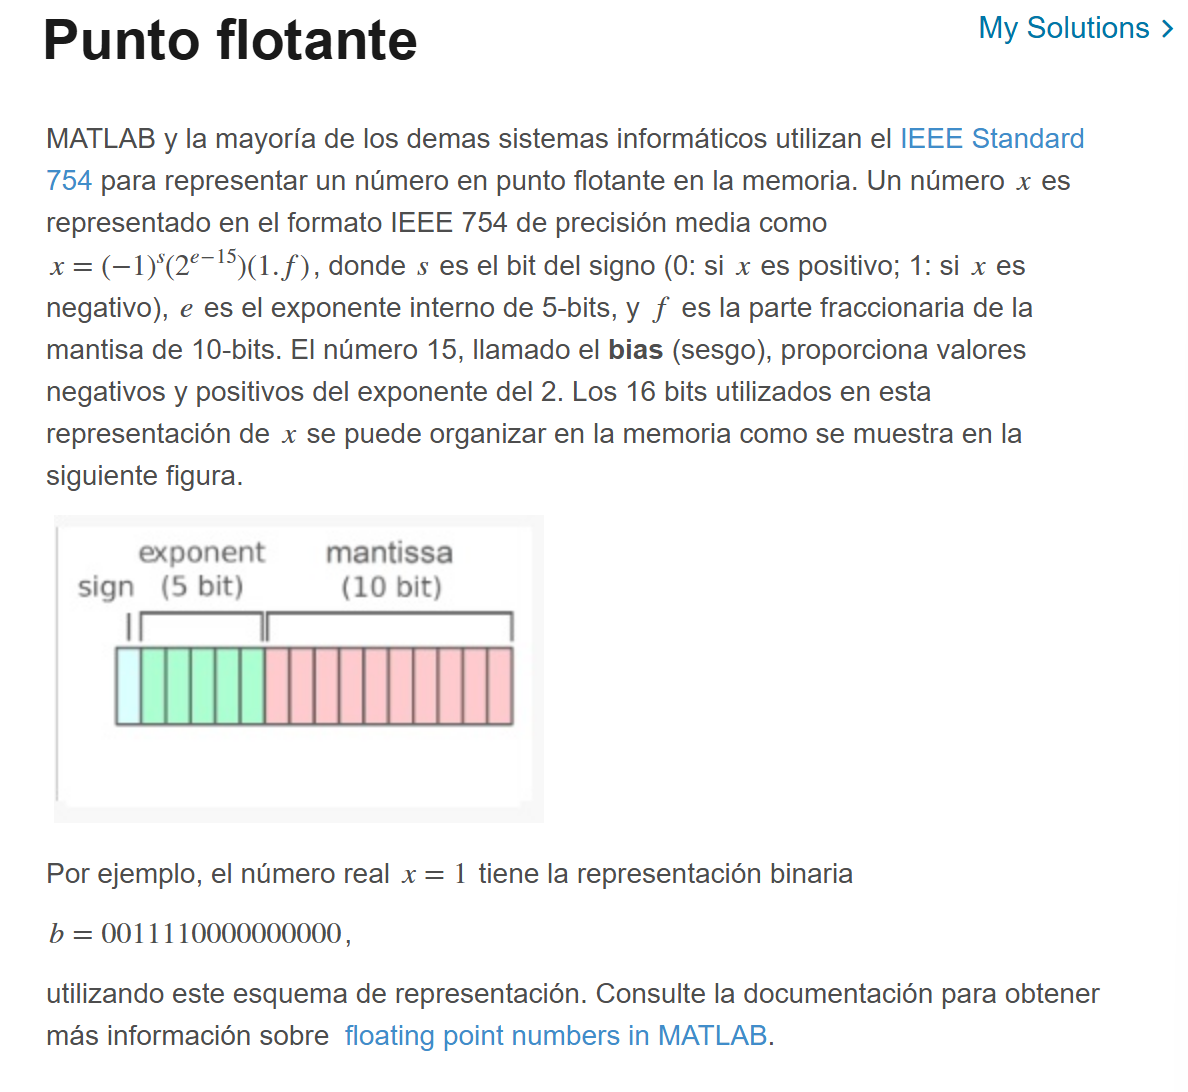

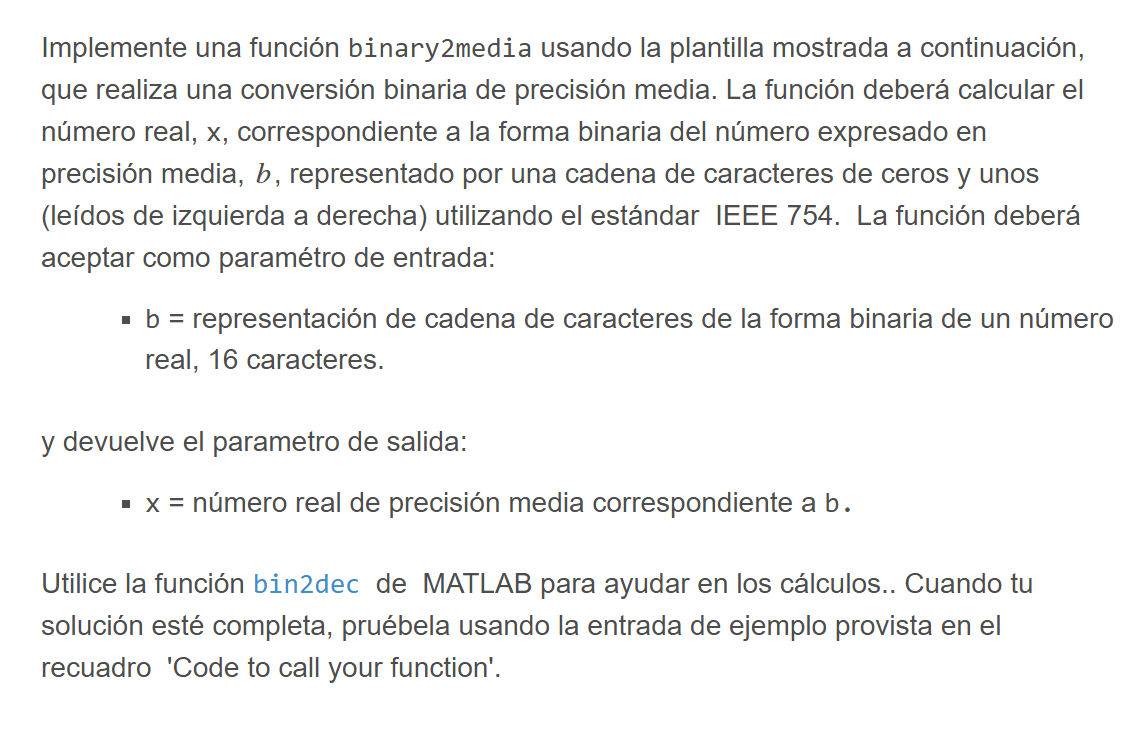

b = '0100000000000000';
x = binary2media(b)

b_sign = '0'

b_exp = '10000'

b_mant = '0000000000'

d_sign =      0


expon =     16


d_mant =      0


x =      2


c = '1100000000000000';
d = binary2media(c)

b_sign = '1'

b_exp = '10000'

b_mant = '0000000000'

d_sign =      1


expon =     16


d_mant =      0


d =     -2


Pregunta 5

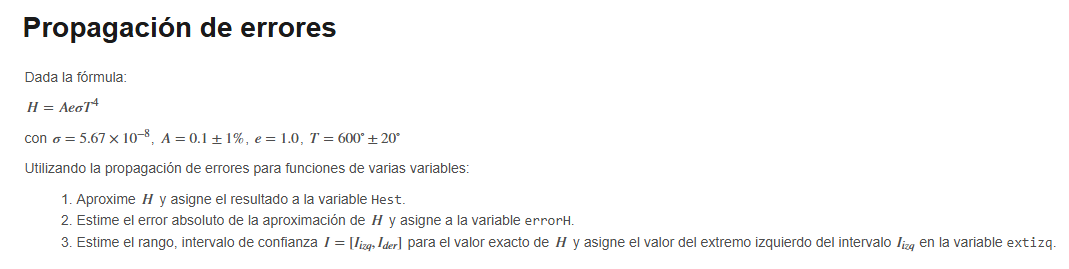

format long
syms A T
% aproxime el valor de H
e = 1.0;
o = 5.67*10^(-8)

o =      5.670000000000000e-08



H = A*e*o*T^(4);
Hest= double(subs(H,[A,T],[0.1,600]))

Hest =      7.348320000000000e+02



% estime el error absoluto

H_difA = diff(H,A)

$$H\_difA = \frac{2142065436629671\,T^{4}}{37778931862957161709568}$$

H_difT = diff(H,T)

$$H\_difT = \frac{2142065436629671\,A\,T^{3}}{9444732965739290427392}$$

H_difA_val = double(subs(H_difA,[A,T],[0.1,600]))

H_difA_val =      7.348320000000000e+03


H_difT_val = double(subs(H_difT,[A,T],[0.1,600]))

H_difT_val =    4.898880000000000



errorH= abs(H_difA_val)*0.01*0.1 + abs(H_difT_val)*20

errorH =      1.053259200000000e+02



% encuentre el extremo izquierdo del intervalo de confianza
extizq= Hest - errorH

extizq =      6.295060800000000e+02


Pregunta 6

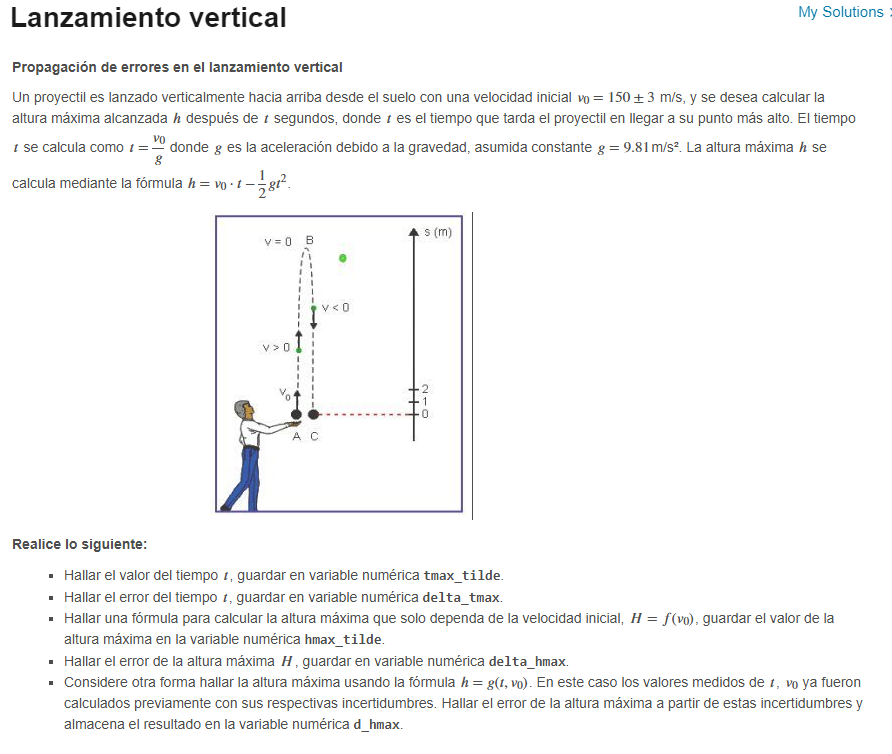

format long

v0_tilde = 150; % Velocidad inicial en m/s
delta_v0 = 3; % Error en la velocidad inicial en m/s
g = 9.81; % Aceleración debida a la gravedad en m/s²

% Calcular el tiempo al punto más alto
tmax_tilde = v0_tilde / g; % valor del tiempo cuando altura es maxima
delta_tmax = delta_v0/g; % error del tiempo cuando altura maxima

% Fórmula para la altura máxima dependiente solo de v0
hmax_tilde = (v0_tilde^(2) )/ (2*g)

hmax_tilde =      1.146788990825688e+03



% Error de la altura máxima
delta_hmax = (2*v0_tilde*delta_v0) / (2*g)

delta_hmax =   45.871559633027523



syms t v0
h_formula = v0 * t - 0.5 * g * t^2;

% Cálculo del error propagado en la altura máxima
h_diff_v0 = diff(h_formula,v0)

$$h\_diff\_v0 = t$$

h_diff_t = diff(h_formula,t)

$$h\_diff\_t = v_{0}-\frac{981\,t}{100}$$


h_diff_v0_val = double(subs(h_diff_v0,[t,v0],[tmax_tilde,v0_tilde]))

h_diff_v0_val =   15.290519877675841


h_diff_t_val = double(subs(h_diff_t,[t,v0],[tmax_tilde,v0_tilde]))

h_diff_t_val =      0



d_hmax = abs(h_diff_v0_val)*delta_v0 + abs(h_diff_t_val)*delta_tmax

d_hmax =   45.871559633027523


Pregunta 7

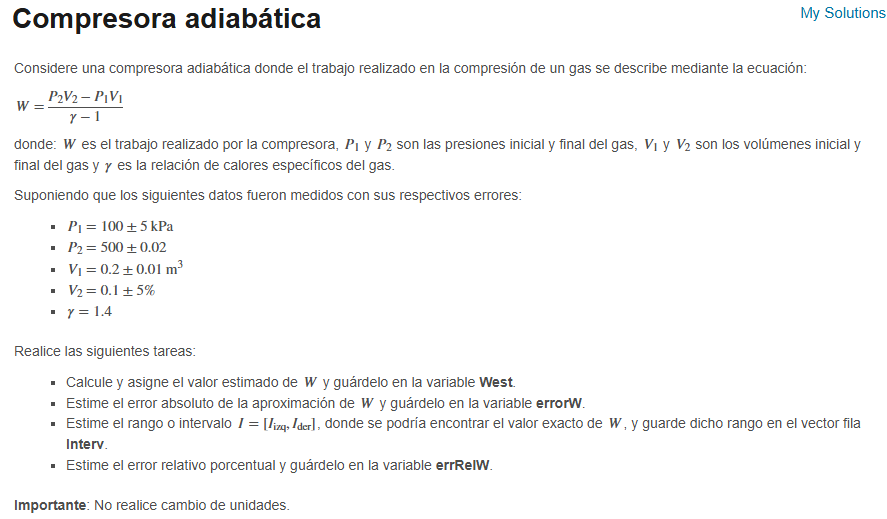

% Datos medidos con errores
P1_val = 100;
d_P1_val = 5;
d_P2_val = 0.02;
d_V1_val = 0.01;
d_V2_val = 0.05*0.1;
P2_val = 500;
V1_val = 0.2;
V2_val = 0.1;
gamma_val = 1.4;

% Ecuación:
syms P1 P2 V2 V1
W = (P2 * V2 - P1 * V1) / (gamma_val - 1);
West = double(subs(W,[P1,P2,V2,V1],[P1_val,P2_val,V2_val,V1_val]))

West =     75




W_func_dif_P2 = diff(W,P2)

$$W\_func\_dif\_P2 = \frac{5\,V_{2}}{2}$$

W_func_dif_P1 = diff(W,P1)

$$W\_func\_dif\_P1 = -\frac{5\,V_{1}}{2}$$

W_func_dif_V2 = diff(W,V2)

$$W\_func\_dif\_V2 = \frac{5\,P_{2}}{2}$$

W_func_dif_V1 = diff(W,V1)

$$W\_func\_dif\_V1 = -\frac{5\,P_{1}}{2}$$


W_dif_P2_val = double(subs(W_func_dif_P2,[P1,P2,V2,V1],[P1_val,P2_val,V2_val,V1_val]))

W_dif_P2_val =    0.250000000000000


W_dif_P1_val = double(subs(W_func_dif_P1,[P1,P2,V2,V1],[P1_val,P2_val,V2_val,V1_val]))

W_dif_P1_val =   -0.500000000000000


W_dif_V2_val = double(subs(W_func_dif_V2,[P1,P2,V2,V1],[P1_val,P2_val,V2_val,V1_val]))

W_dif_V2_val =         1250


W_dif_V1_val = double(subs(W_func_dif_V1,[P1,P2,V2,V1],[P1_val,P2_val,V2_val,V1_val]))

W_dif_V1_val =   -250


errorW = abs(W_dif_P2_val)*d_P2_val + abs(W_dif_P1_val)*d_P1_val + abs(W_dif_V2_val)*d_V2_val + abs(W_dif_V1_val)*d_V1_val

errorW =   11.255000000000001



Interv = [West-errorW West+errorW]

Interv =   63.744999999999997  86.254999999999995



errRelW = errorW/West * 100

errRelW =   15.006666666666668


% Variables solicitadas
% West
% errorW
% Interv
% errRelW

Pregunta 8

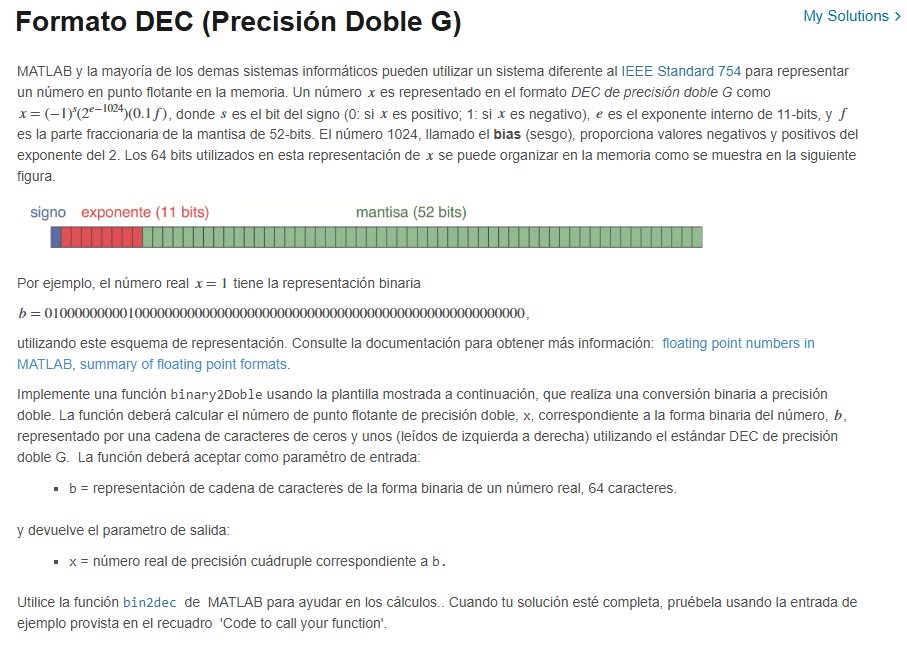

b='0100000000010000000000000000000000000000000000000000000000000000';
x=binary2Doble(b)

b_sign = '0'

b_exp = '10000000001'

b_mant = '0000000000000000000000000000000000000000000000000000'

d_sign =      0


expon =         1025


d_mant =      0


x =      4


x =      4


Pregunta 9

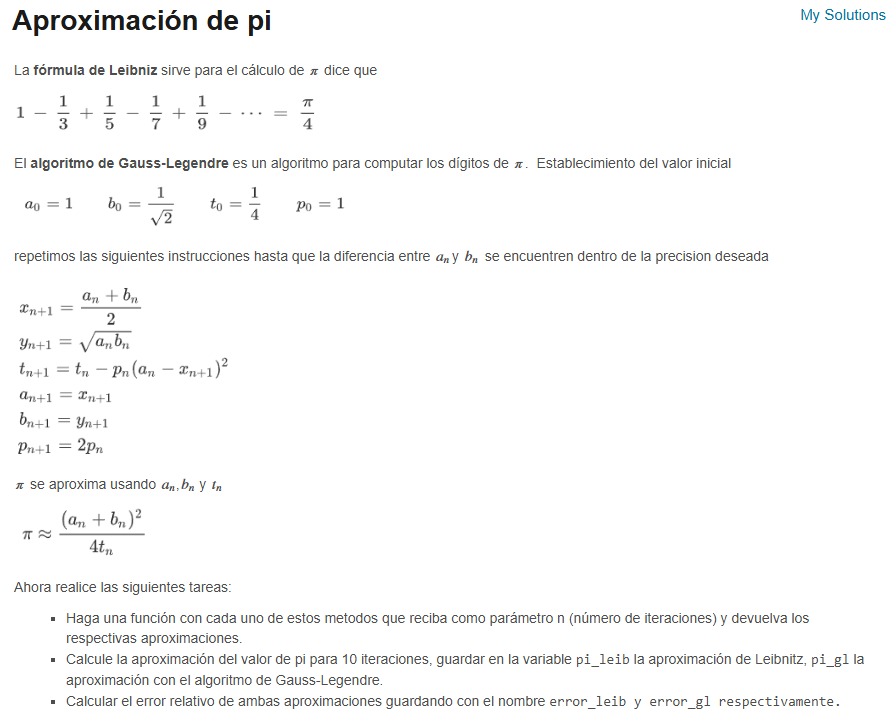

%%%%%%%%%%%%% halle las aproximaciones de pi y los errores asociados %%%%%%%%%%%%%

% Aproximación usando Leibniz 
pi_leib = leibniz_pi(10)

pi_leib =    3.041839618929403


error_leib = abs((pi - pi_leib)) / pi % Aproximación usando Gauss-Legendre 

error_leib =    0.031752377109236



pi_gl = gauss_legendre_pi(10)

pi_gl =    3.141592653589794


error_gl = abs((pi - pi_gl)) / pi

error_gl =      2.827159716856459e-16




%%%%%%%%%%%%% funciones a completar %%%%%%%%%%%%%
pi_ap = leibniz_pi(10)

pi_ap =    3.041839618929403


Pregunta 10

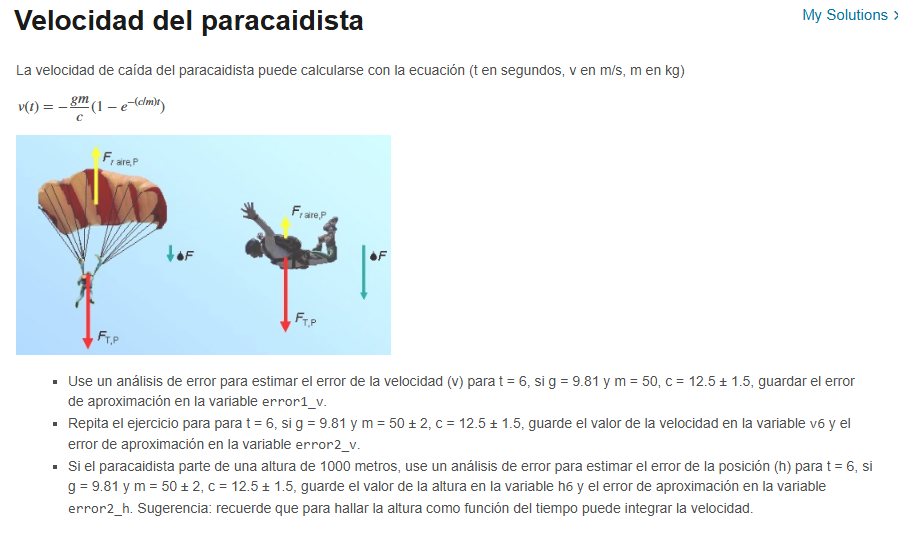

clear
format long 
g = 9.81;  % Aceleración debido a la gravedad
%m = 50;    % Masa del paracaidista 
t = 6;     % Instante de tiempo de análisis
d_c = 1.5;
d_m = 2;

% primera parte
syms c 
v = (-(g*50)/c) * (1 - exp(-(c/50)*t ) )

$$v = \frac{981\,\left({\mathrm{e}}^{-\frac{3\,c}{25}}-1\right)}{2\,c}$$


v_dif_c = diff(v,c);
v_dif_c_val = double(subs(v_dif_c,[c],[12.5]))

v_dif_c_val =    1.388074503155123


error1_v= abs(v_dif_c_val)*d_c % bien

error1_v =    2.082111754732684




% segunda parte
syms c m
v2 =  (-(g*m)/c) * (1 - exp(-(c/m)*t ) );
v6 = double(subs(v2,[c,m],[12.5,50])) % bien

v6 =  -30.484372515775615



v2_dif_c = diff(v2,c);
v2_dif_m = diff(v2,m);

v2_dif_c_val = double(subs(v2_dif_c,[c,m],[12.5,50]))

v2_dif_c_val =    1.388074503155123


v2_dif_m_val = double(subs(v2_dif_m,[c,m],[12.5,50]))

v2_dif_m_val =   -0.347018625788781



error2_v=abs(v2_dif_m_val)*d_m + abs(v2_dif_c_val)*d_c % bien

error2_v =    2.776149006310245



% tercera parte
syms c m t % le agregue t porque es en funcion de t pero no se si este bn
v3 =  (-(g*m)/c) * (1 - exp(-(c/m)*t ) )

$$v3 = \frac{981\,m\,\left({\mathrm{e}}^{-\frac{c\,t}{m}}-1\right)}{100\,c}$$

h0 = 1000; % Altura de partida
c_val = 12.5;
m_val = 50;

h = h0 + int(v, t)

$$h = \frac{981\,t\,\left({\mathrm{e}}^{-\frac{3\,c}{25}}-1\right)}{2\,c}+1000$$

% Derivadas parciales de la altura respecto a c y m 
h_dif_c = diff(h, c); 
h_dif_m = diff(h, m); 

% Calcular la altura y su error 
h6 = double(subs(h, [c, m,t], [12.5, 50 ,6]))

h6 =      8.170937649053463e+02



h_dif_c_val = double(subs(h_dif_c, [c, m,t], [c_val, m_val,6])); 
h_dif_m_val = double(subs(h_dif_m, [c, m,t], [c_val, m_val,6])); 

error2_h = abs(h_dif_c_val) * 1.5 + abs(h_dif_m_val) *2

error2_h =   12.492670528396104


Funciones:

Pregunta 9:

function pi_ap = leibniz_pi(n)
% n: número de iteraciones
% pi_ap: valor aproximado de pi

    % complete aquí
    pi_ap = 0;
    for i= 0:n-1
        pi_ap = pi_ap +((-1)^i)*(1/(2*i+1));
    end
    
    pi_ap = 4*pi_ap;
end

function pi_approx = gauss_legendre_pi(n)
% n: número de iteraciones
% pi_approx: valor aproximado de pi
    % complete aquí
    a = 1; 
    b = 1/sqrt(2); 
    t = 1/4; 
    p = 1; 
    for k = 1:n 
        a_next = (a + b) / 2; 
        b = sqrt(a * b); 
        t = t - p * (a - a_next)^2; 
        a = a_next; 
        p = 2 * p; 
    end
    
    pi_approx = ((a + b)^2) / (4 * t); 
end

Pregunta 8:

function x = binary2Doble(b)

% Extraiga los bits de signo, exponente y mantisa de la cadena.
b_sign = b(1)
b_exp=b(2:12)
b_mant=b(13:end)

% Convierte los bits a valores decimales.
d_sign=bin2dec(b_sign)

% exponente
expon = bin2dec(b_exp)
% mantisa
d_mant = bin2dec(b_mant)*2^(-52)

% Convierte a un número real usando el DEC Standard.
x = ((-1)^(d_sign))*(2^(expon-1023))*(1+d_mant)
end

Pregunta 4:

function x = binary2media(b)

% Extraiga los bits de signo, exponente y mantisa de la cadena.
b_sign = b(1)
b_exp=b(2:6)
b_mant=b(7:16)

% Convierte los bits a valores decimales.
d_sign=bin2dec(b_sign)

% exponente
expon = bin2dec(b_exp)
% mantisa
d_mant = bin2dec(b_mant)*2^(-10)

% Convierte a un número real usando el IEEE Standard 754.
x =((-1)^(d_sign))*(2^(expon-15))*(1+d_mant);
end